% Limestone Thickness and cluster plots
%read in excel file 1 to find log(average drip per 15 minutes) and log (COV)
%plot 3 graphs excel file 1 log results and skewness vs excel file 2 with logger thickness
%1.limestone thicknes vs log(average drip per 15 min) or discharge (L/secx10^-6)
%2.limestone thicknes vs skweness
%3.limestone thicknes vs log (COV)

% Clear workspace and command window
clear;
clc;

% Read data from Excel
data = readtable('Overburden_data.xlsx');

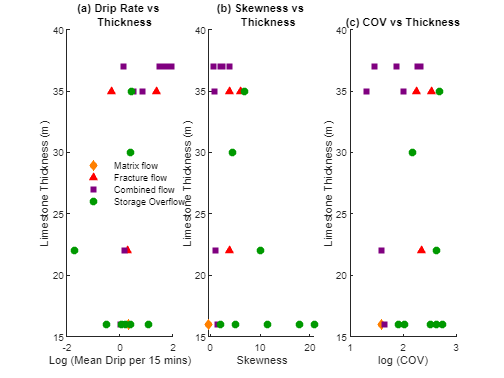


% Extract relevant columns
Site = data{:, 1};        % Site names in column 1
Thickness = data{:, 2};  % Assuming Thickness is in column 2
Drip = data{:, 3};      % Assuming Drip count is in column 3
COV = data{:, 4};       % Assuming COV is in column 4
Skewness = data{:, 5};  % Assuming Skewness is in column 5

% Define clusters (indices of rows corresponding to each cluster)
clusters = {
    6                            % Cluster 1 Matrix
    [8, 16, 18],                 % Cluster 2 Fracture
    [7, 10, 12, 13, 14, 15, 19, 20], % Cluster 3 Combined
    [1, 2, 3, 4, 5, 9, 11, 17],  % Cluster 4 Storage   
};

% % Color options for the clusters (4 unique colors)
% colors = lines(4);  % Use MATLAB's 'lines' colormap for distinct colors

% Define custom colors: orange, green, purple, red
colors = [
    1.0, 0.5, 0.0;  % orange
    1.0, 0.0, 0.0   % red
    0.5, 0.0, 0.5;  % purple
    0.0, 0.6, 0.0;  % green
];



% Marker styles for the clusters (4 unique markers)
markers = {'d', '^','s', 'o'}; % Circle, Square, Triangle, Diamond

% Create a new figure for plotting
figure;

% Create a 1x3 grid of subplots
tiledlayout(1, 3, 'TileSpacing', 'loose');

% Plot Thickness vs Drip Count
% nexttile;
subplot(1, 3, 1); % First subplot
hold on;
for i = 1:length(clusters)
    cluster_idx = clusters{i};
    plot(Drip(cluster_idx), Thickness(cluster_idx), markers{i}, ...
        'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', colors(i, :));
    % Add labels
%     for j = 1:length(cluster_idx)
%         text(Drip(cluster_idx(j)), Thickness(cluster_idx(j)), Site{cluster_idx(j)}, ...
%             'FontSize', 8, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
%     end
end
hold off;
xlabel('Log (Mean Drip per 15 mins)');
ylabel('Limestone Thickness (m)');
title(sprintf('(a) Drip Rate vs \n   Thickness'));

% Add a legend to the first subplot
legend({'Matrix flow','Fracture flow','Combined flow', 'Storage Overflow' }, 'Location', 'west', 'Box', 'off');


% Plot Thickness vs Skewness
%nexttile;
subplot(1, 3, 2); % Second subplot
hold on;
for i = 1:length(clusters)
    cluster_idx = clusters{i};
    plot(Skewness(cluster_idx), Thickness(cluster_idx), markers{i}, ...
        'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', colors(i, :));
    % Add labels
%     for j = 1:length(cluster_idx)
%         text(Skewness(cluster_idx(j)), Thickness(cluster_idx(j)), Site{cluster_idx(j)}, ...
%             'FontSize', 8, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
%     end
end
hold off;
xlabel('Skewness');
ylabel('Limestone Thickness (m)');
title(sprintf('(b) Skewness vs \n    Thickness'));


% Plot Thickness vs COV
%nexttile;
subplot(1, 3, 3); % Third subplot
hold on;
for i = 1:length(clusters)
    cluster_idx = clusters{i};
    plot(COV(cluster_idx), Thickness(cluster_idx), markers{i}, ...
        'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', colors(i, :));
%     Add labels
%     for j = 1:length(cluster_idx)
%         text(COV(cluster_idx(j)), Thickness(cluster_idx(j)), Site{cluster_idx(j)}, ...
%             'FontSize', 8, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
%      end
end
hold off;
xlabel('log (COV)');
ylabel('Limestone Thickness (m)');
title(sprintf('(c) COV vs Thickness'));


% Add a legend to the final subplot
%legend({'Storage Overflow', 'Combined flow', 'Fracture flow', 'Matrix flow'}, 'Location', 'west', 'Box', 'off');
